Code to convert bonn dataset to .mat files 

FileList = dir('*.txt');
disp('files in pathway:     ')

files in pathway:     


disp(numel(FileList))

   100



for a=1:numel(FileList)
    readout={a FileList(a).name};
    disp(readout)
end

    [1]    'Z001.txt'



    [2]    'Z002.txt'



    [3]    'Z003.txt'



    [4]    'Z004.txt'



    [5]    'Z005.txt'



    [6]    'Z006.txt'



    [7]    'Z007.txt'



    [8]    'Z008.txt'



    [9]    'Z009.txt'



    [10]    'Z010.txt'



    [11]    'Z011.txt'



    [12]    'Z012.txt'



    [13]    'Z013.txt'



    [14]    'Z014.txt'



    [15]    'Z015.txt'



    [16]    'Z016.txt'



    [17]    'Z017.txt'



    [18]    'Z018.txt'



    [19]    'Z019.txt'



    [20]    'Z020.txt'



    [21]    'Z021.txt'



    [22]    'Z022.txt'



    [23]    'Z023.txt'



    [24]    'Z024.txt'



    [25]    'Z025.txt'



    [26]    'Z026.txt'



    [27]    'Z027.txt'



    [28]    'Z028.txt'



    [29]    'Z029.txt'



    [30]    'Z030.txt'



    [31]    'Z031.txt'



    [32]    'Z032.txt'



    [33]    'Z033.txt'



    [34]    'Z034.txt'



    [35]    'Z035.txt'



    [36]    'Z036.txt'



    [37]    'Z037.txt'



    [38]    'Z038.txt'



    [39]    'Z039.txt'



    [40]    'Z040.txt'



    [41]    'Z041.txt'



    [42]    'Z042.txt'



    [43]    'Z043.txt'



    [44]    'Z044.txt'



    [45]    'Z045.txt'



    [46]    'Z046.txt'



    [47]    'Z047.txt'



    [48]    'Z048.txt'



    [49]    'Z049.txt'



    [50]    'Z050.txt'



    [51]    'Z051.txt'



    [52]    'Z052.txt'



    [53]    'Z053.txt'



    [54]    'Z054.txt'



    [55]    'Z055.txt'



    [56]    'Z056.txt'



    [57]    'Z057.txt'



    [58]    'Z058.txt'



    [59]    'Z059.txt'



    [60]    'Z060.txt'



    [61]    'Z061.txt'



    [62]    'Z062.txt'



    [63]    'Z063.txt'



    [64]    'Z064.txt'



    [65]    'Z065.txt'



    [66]    'Z066.txt'



    [67]    'Z067.txt'



    [68]    'Z068.txt'



    [69]    'Z069.txt'



    [70]    'Z070.txt'



    [71]    'Z071.txt'



    [72]    'Z072.txt'



    [73]    'Z073.txt'



    [74]    'Z074.txt'



    [75]    'Z075.txt'



    [76]    'Z076.txt'



    [77]    'Z077.txt'



    [78]    'Z078.txt'



    [79]    'Z079.txt'



    [80]    'Z080.txt'



    [81]    'Z081.txt'



    [82]    'Z082.txt'



    [83]    'Z083.txt'



    [84]    'Z084.txt'



    [85]    'Z085.txt'



    [86]    'Z086.txt'



    [87]    'Z087.txt'



    [88]    'Z088.txt'



    [89]    'Z089.txt'



    [90]    'Z090.txt'



    [91]    'Z091.txt'



    [92]    'Z092.txt'



    [93]    'Z093.txt'



    [94]    'Z094.txt'



    [95]    'Z095.txt'



    [96]    'Z096.txt'



    [97]    'Z097.txt'



    [98]    'Z098.txt'



    [99]    'Z099.txt'



    [100]    'Z100.txt'




g= 1:length(FileList)

g =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


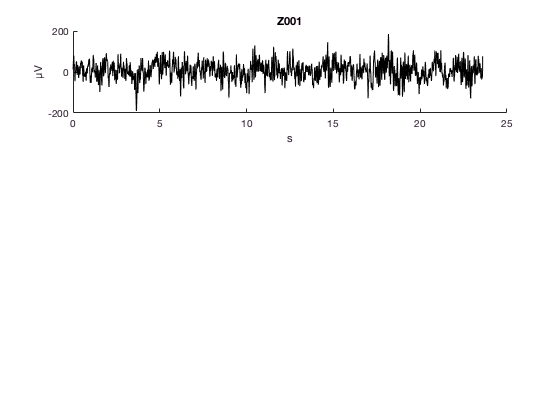

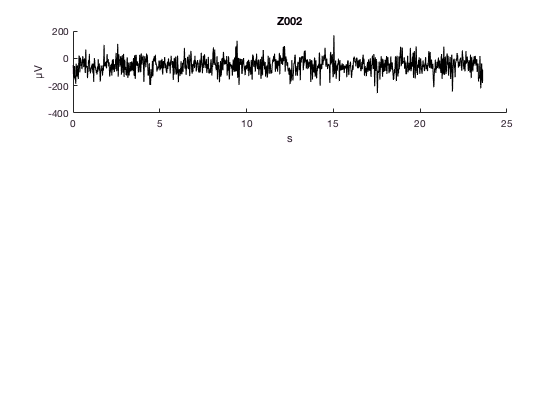

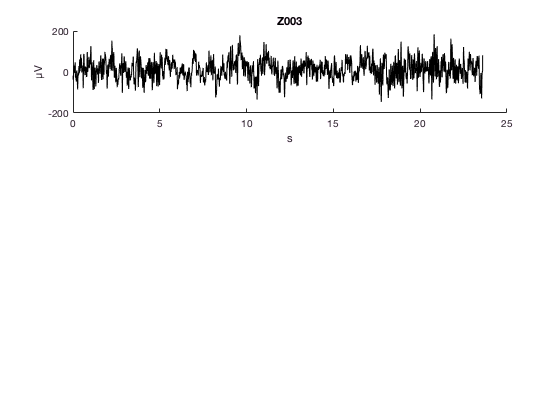

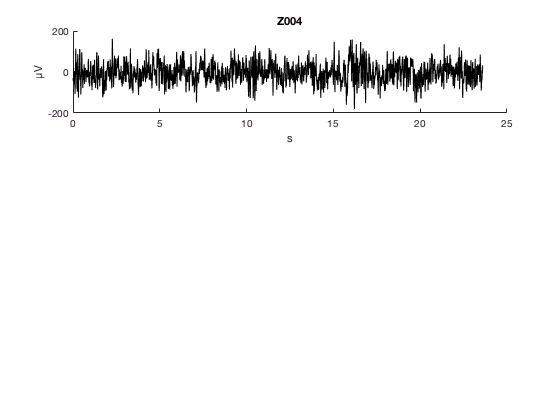

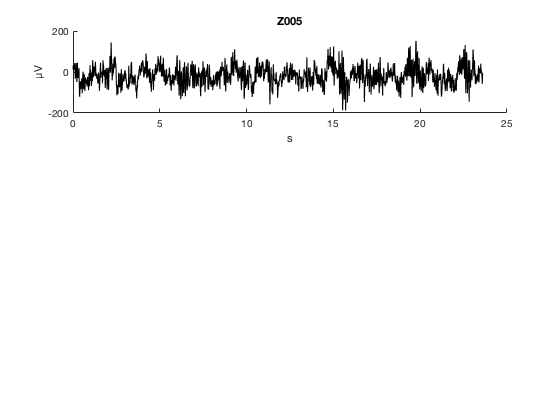

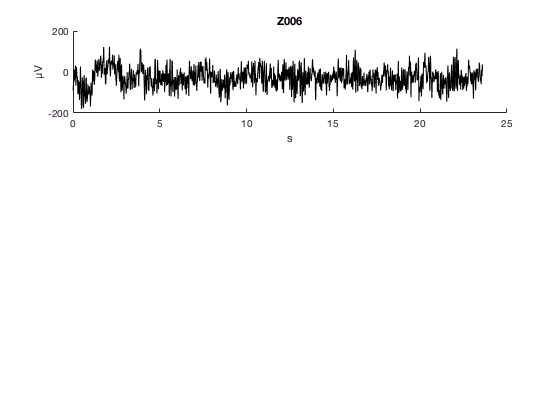

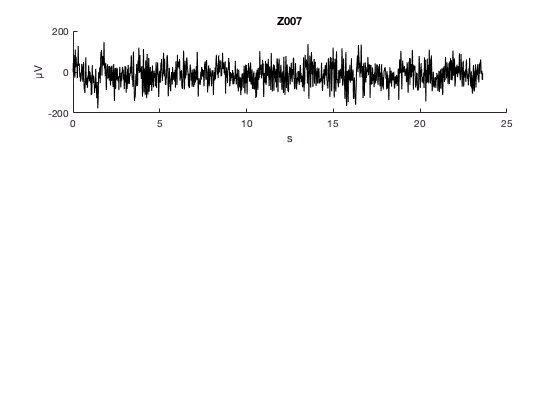

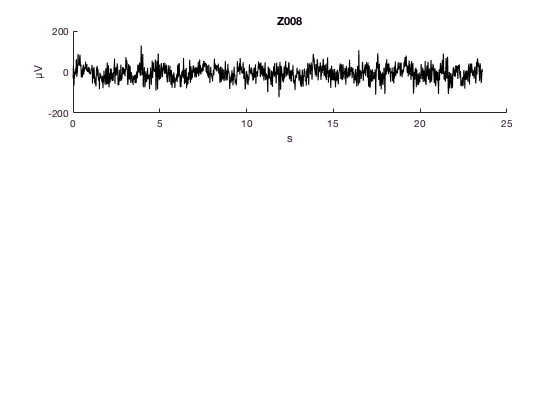


 for k = g
    
     %load (FileList(k).name);
     input_name = FileList(k).name;            
     [~, name, ~] = fileparts (input_name); 
    
    EEG = load(input_name);
    
    %  save ([name '_Bonn.mat'],'EEG')
    
    figure
    subplot(3,1,1)
    t = length(EEG/173.61); 
    plot((1/173.61:1/173.61:t/173.61),EEG,'k')
    title(name)
    ax = gca;
    ax.Box = 'off';
    ax.YLabel.String = 'µV';
    ax.XLabel.String = 's';
        
       saveas(gcf,[name 'BonnFig.png']) 
         
        
 end